close all 
%FEEDBACK CONTROLS PROJECT 
%Adam Chung 
%12/02/2020

%INIT
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
robot = importrobot("ROM_bot.urdf") %Create rigidBodyTree obj

robot =   rigidBodyTree with properties:

     NumBodies: 2
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'lever_arm'  'handle'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


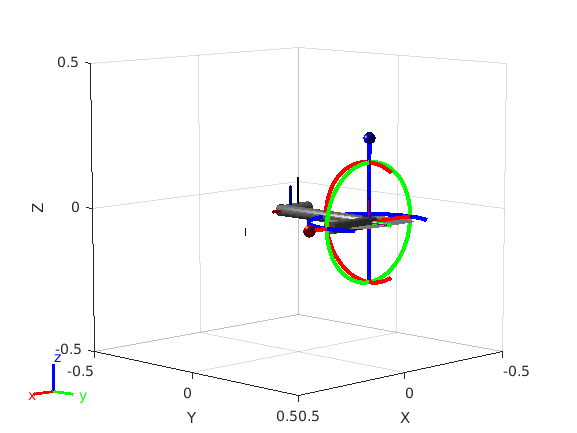

iviz = interactiveRigidBodyTree(robot,"MarkerBodyName","handle"); %Sim enviroment
ax = gca;
plane = collisionBox(0,0,0.025); %Floor init
plane.Pose = trvec2tform([0.25 0 -0.055]); %Floor pose
show(plane,'Parent', ax);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Define and plot Trajectory 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%trajectory = 1 ==> Pentagon 
%trajectory = 2 ==> Sine wave
%trajectory = 3 ==> Random 
ROM = -pi/3; 
reps = 10; 
q_waypts = [ROM 0]; %1 Rep 
for i = 1:reps
    q_waypts = [q_waypts q_waypts]; 
end



%Simulate desired trajectories with controllers and choose which one to show
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
simout_CPM = sim('CPM.slx');

Error due to multiple causes.

Caused by:
    Error using simulate (line 34)
    Matrix multiply dimensions propagation error. Error occurred while setting 'Input Port 1' of 'CPM/CPM Controller /EE-Kinematics/Matrix Multiply2' to have the dimensions [6 x 2]. A possible cause for this error is that these dimensions do not agree with the partial dimensions information present on other ports
    Error using 

%simout_PD = sim('PD.slx'); 

%controller = 1 ==> Computed Torque Control
%controller = 2 ==> PD Control 

controller = 3; 
switch controller 
    case 1 
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_CPM.tout)/(max(simout_CPM.tout)));
        for i = 1:length(simout_CPM.tout)
            iviz.Configuration = simout_CPM.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end
        q = simout_CPM.q_cpm; 
        q_desired = simout_CPM.q_desired; 
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        hold off
    case 2
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_PD.tout)/(max(simout_PD.tout)));
        for i = 1:length(simout_PD.tout)
            iviz.Configuration = simout_PD.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end  
        q = simout_PD.q_pd; 
        q_desired = simout_PD.q_desired; 
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        hold off
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%